%% Clear workspace and load function folder
clear; close all;
addpath('functions');  % Access modular functions

%% Configuration Parameters
cellNumber = 290;
freqGHz = 3.5;
%   Valid scenario strings:
%     - 'RURAL_MACROCELL'
%     - 'URBAN_MICROCELL'
%     - 'URBAN_MACROCELL'
%     - 'INDOOR_OPEN_OFFICE'
%     - 'INDOOR_MIXED_OFFICE'
%     - 'INDOOR_SHOPPING_MALL'
scenario = 'URBAN_MICROCELL';

% Get correlation distances and standard deviations for LOS and NLOS
[corrDistLOS, corrDistNLOS, stdDevLOS, stdDevNLOS] = adjust_parameters(scenario);
distance = min(corrDistNLOS, corrDistLOS) * 0.5;

% Define spatial axes (both x and y are used; assuming a square map)
axisVals = distance * linspace(-cellNumber/2, cellNumber/2, cellNumber);

%% Generate various maps
% Pathloss maps for LOS and NLOS conditions
mapPathlossLOS  = generate_pathloss_map(scenario, true,  distance, cellNumber, freqGHz);
mapPathlossNLOS = generate_pathloss_map(scenario, false, distance, cellNumber, freqGHz);

% Shadow fading maps for LOS and NLOS with spatial filtering
mapShadowLOS  = generate_filtered_matrix(corrDistLOS,  distance, stdDevLOS,  cellNumber);
mapShadowNLOS = generate_filtered_matrix(corrDistNLOS, distance, stdDevNLOS, cellNumber);

% Boolean map to identify LOS conditions (true = LOS, false = NLOS)
mapLOSBool = map_LOS(distance, cellNumber, scenario);

% Calculate macroscopic fading maps from shadow fading and pathloss
mapMacroscopicLOS  = mapShadowLOS  - mapPathlossLOS;
mapMacroscopicNLOS = mapShadowNLOS - mapPathlossNLOS;

% Final combined macroscopic fading map using the boolean LOS map
finalMacroscopicMap = mapLOSBool .* mapMacroscopicLOS + (~mapLOSBool) .* mapMacroscopicNLOS;
%finalMacroscopicMap = mapMacroscopicNLOS; 
%% Sanity Check for Invalid Values
if any(isnan(finalMacroscopicMap(:))) || any(isinf(finalMacroscopicMap(:)))
    disp('finalMacroscopicMap contains NaN or Inf.');
end

%% Save Final Map to JSON File
jsonStruct.cell_number = cellNumber;
jsonStruct.cell_size   = distance;
jsonStruct.map         = finalMacroscopicMap;

jsonData = jsonencode(jsonStruct);
outputFolder = 'maps';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end
jsonFilename = fullfile(outputFolder, ['macroscopic_fading_map_' scenario '_' num2str(freqGHz) '.json']);

fid = fopen(jsonFilename, 'w');
if fid == -1
    error('Could not open file for writing');
end
fwrite(fid, jsonData, 'char');
fclose(fid);



## Plotting

range_m = 1500;

% Índices dentro de ese rango
idx = find(axisVals >= -range_m & axisVals <= range_m);
xVals = axisVals(idx);
yVals = axisVals(idx);
mapCrop = finalMacroscopicMap(idx, idx);
figure;
surf(xVals, yVals, mapCrop, 'EdgeColor', 'none');

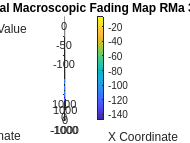

title('3D Surface of Final Macroscopic Fading Map RMa 3.5GHz');
xlabel('X Coordinate'); ylabel('Y Coordinate'); zlabel('Fading Value'); colorbar;

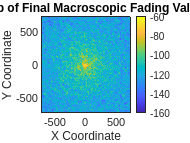


figure;
imagesc(axisVals, axisVals, finalMacroscopicMap);
axis xy; title('2D Map of Final Macroscopic Fading Values');
xlabel('X Coordinate'); ylabel('Y Coordinate'); colorbar;
colorbar;
caxis([-160 -60]);

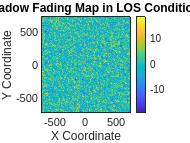


figure;
imagesc(axisVals, axisVals, mapShadowLOS);
axis xy; title('2D Shadow Fading Map in LOS Conditions');
xlabel('X Coordinate'); ylabel('Y Coordinate'); colorbar;

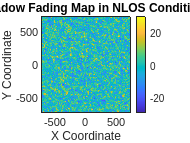


figure;
imagesc(axisVals, axisVals, mapShadowNLOS);
axis xy; title('2D Shadow Fading Map in NLOS Conditions');
xlabel('X Coordinate'); ylabel('Y Coordinate'); colorbar;

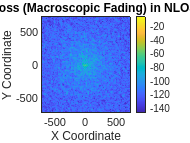


figure;
imagesc(axisVals, axisVals, mapMacroscopicNLOS);
axis xy; title('2D Map of Pathloss (Macroscopic Fading) in NLOS Conditions');
xlabel('X Coordinate'); ylabel('Y Coordinate'); colorbar;

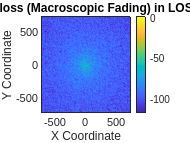


figure;
imagesc(axisVals, axisVals, mapMacroscopicLOS);
axis xy; title('2D Map of Pathloss (Macroscopic Fading) in LOS Conditions');
xlabel('X Coordinate'); ylabel('Y Coordinate'); colorbar;

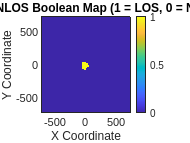


figure;
imagesc(axisVals, axisVals, double(mapLOSBool));
axis xy; title('2D LOS/NLOS Boolean Map (1 = LOS, 0 = NLOS)');
xlabel('X Coordinate'); ylabel('Y Coordinate'); colorbar;